# Algoritmo_di_Bisezione

***Data una generica funzione f(x) considerata in  un intervallo [a ,b]. L'algoritmo di bisezione calcola il punto in cui f(x)=0.***

## Sintassi

- `x = algoritmo_di_bisezione(f,x0)` 

- `x = algoritmo_di_bisezione(f,x0,TOL)` 

- `x = algoritmo_di_bisezione(f,x0,TOL,NMAX)`

-  `[x uscita] = algoritmo_di_bisezione()` 

-  `[x uscita graf] = algoritmo_di_bisezione()` 

**Descrizione**

- `x = algoritmo_di_bisezione(f,x0)` restituisce il valore dell'approssimazione dello zero nell'intervallo specificato x0=[a b].

- `x = algoritmo_di_bisezione(f,x0,TOL)` l'accuratezza della soluzione è determinata dal valore **TOL**, se omesso TOL=eps.

- `x = algoritmo_di_bisezione(f,x0,TOL,NMAX)`  l'accuratezza della soluzione è determinata dal valore **TOL** e `NMAX` rappresenta il numero massimo di iterazioni eseguibili. Se omessi `TOL=eps, NMAX=500`.

-  `[x uscita] = algoritmo_di_bisezione()` restituisce, oltre al valore dell'approssimazione una struttura *uscita *contenente: `fx `il valore che assume la funzione nel punto x ,`numiter` rappresentante il numero di iterazioni effettuate dell'algoritmo.

-  `[x uscita graf] = algoritmo_di_bisezione()` ritorna una variabile di tipo `char `rappresentante il grafico della funzione e dell'approssimazione a zero determinata.

## Esempi di utilizzo

Calcolare lo zero  di $\text{ }x^2 -4$ nell'intervallo $\left\lbrack 0,4\right\rbrack$.

- `Command Line Matlab`

f =  @(x) x.^2 -4; % funzione handle
x0 = [0 4]; % intervallo  di riferimento
x= algoritmo_di_bisezione(f,x0) %chiamata funzione

x = 2

Calcolare lo zero  di $x^2 -4$ nell'intervallo $\left\lbrack 0,4\right\rbrack$ e  TOL= ${10}^{-10}$

`Command Line Matlab`

f =  @(x) 2-exp(-x)-sqrt(x); % funzione handle
x0 = [0 4]; % intervallo di riferimento
x= algoritmo_di_bisezione(f,x0,10^-10)%chiamata funzione

x = 3.9211

Calcolare lo zero  di $2-e^{-x} \;-\sqrt{x}$ nell'intervallo $\left\lbrack 0,4\right\rbrack$,TOL= ${10}^{-10}$ e NMAX=100.

`Command Line Matlab`

f =  @(x) 2-exp(-x)-sqrt(x); % funzione handle
x0 = [0 4]; % intervallo di riferimento
x= algoritmo_di_bisezione(f,x0,10^-10,100)%chiamata funzione

x = 3.9211

Calcolare lo zero  di $2-e^{-x} \;-\sqrt{x}$ nell'intervallo $\left\lbrack 0,4\right\rbrack$,TOL= ${10}^{-10}$ e NMAX=100. Si richiede anche l'*uscita *contenente: `fx e numiter` .

`Esempio da Command Line Matlab`

f =  @(x) 2-exp(-x)-sqrt(x); % funzione handle
x0 = [0 4]; % intervallo di riferimento
[x,uscita]= algoritmo_di_bisezione(f,x0,10^-10,100)%chiamata funzione

x = 3.9211

uscita = struct with fields:
         fx: -1.5316e-11
    numiter: 34


Calcolare lo zero  di $2-e^{-x} \;-\sqrt{x}$ nell'intervallo $\left\lbrack 0,4\right\rbrack$,TOL= ${10}^{-10}$ e NMAX=100. Si richiede l'uscita ed il grafico della funzione.

`Esempio da Command Line Matlab`

x = 3.9211

uscita = struct with fields:
         fx: -1.5316e-11
    numiter: 34


graf =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×6001 double]
              YData: [1×6001 double]
              ZData: [1×0 double]

  Show all properties


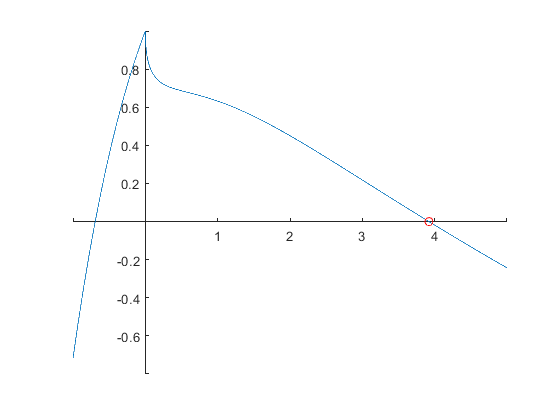

f =  @(x) 2-exp(-x)-sqrt(x); % funzione  handle
x0 = [0 4]; %  intervallo di riferimento
[x,uscita,graf]= algoritmo_di_bisezione(f,x0,10^-10,100)%chiamata funzione

## **Esecuzione da interfaccia grafica**

Si può utilizzare la funzione algoritmo di bisezione attraverso l'interfaccia grafica appositamente implementata. Il comando per utilizzare l'interfaccia è **run MainGui()**`.` 

## Riferimenti

[Docenti.unina.it D'alessio Alessandra](https://www.docenti.unina.it/#!/professor/414c455353414e4452414427414c455353494f444c534c534e3534433630463833394e/login)

[WikiUniversity Metodo di Bisezione](https://it.wikiversity.org/wiki/Metodo_di_bisezione)

## Autori

` Giuseppe Napolano M63000856 Raffaele Formisano M63000912 Giuseppe Romito M63000936`